The purpose of this code is to graph the time interval

data = readmatrix('Data Files/Pressure Files/Measured Pressure/10-Aug-2022 00;32;08.csv');
times = (data(:,1)-datenum('10-Aug-2022 00:32:08'))*1440*60

times = 	1.0e+04 *

    0.0030
    0.0032
    0.0033
    0.0035
    0.0036
    0.0038
    0.0040
    0.0041
    0.0043
    0.0044


intervals = [];
for i = 2:length(times)
    intervals = [intervals, times(i)-times(i-1)];
end
fit(times(2:end)/3600,intervals','poly1')

ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.4943  (0.4921, 0.4965)
       p2 =        1.88  (1.87, 1.889)

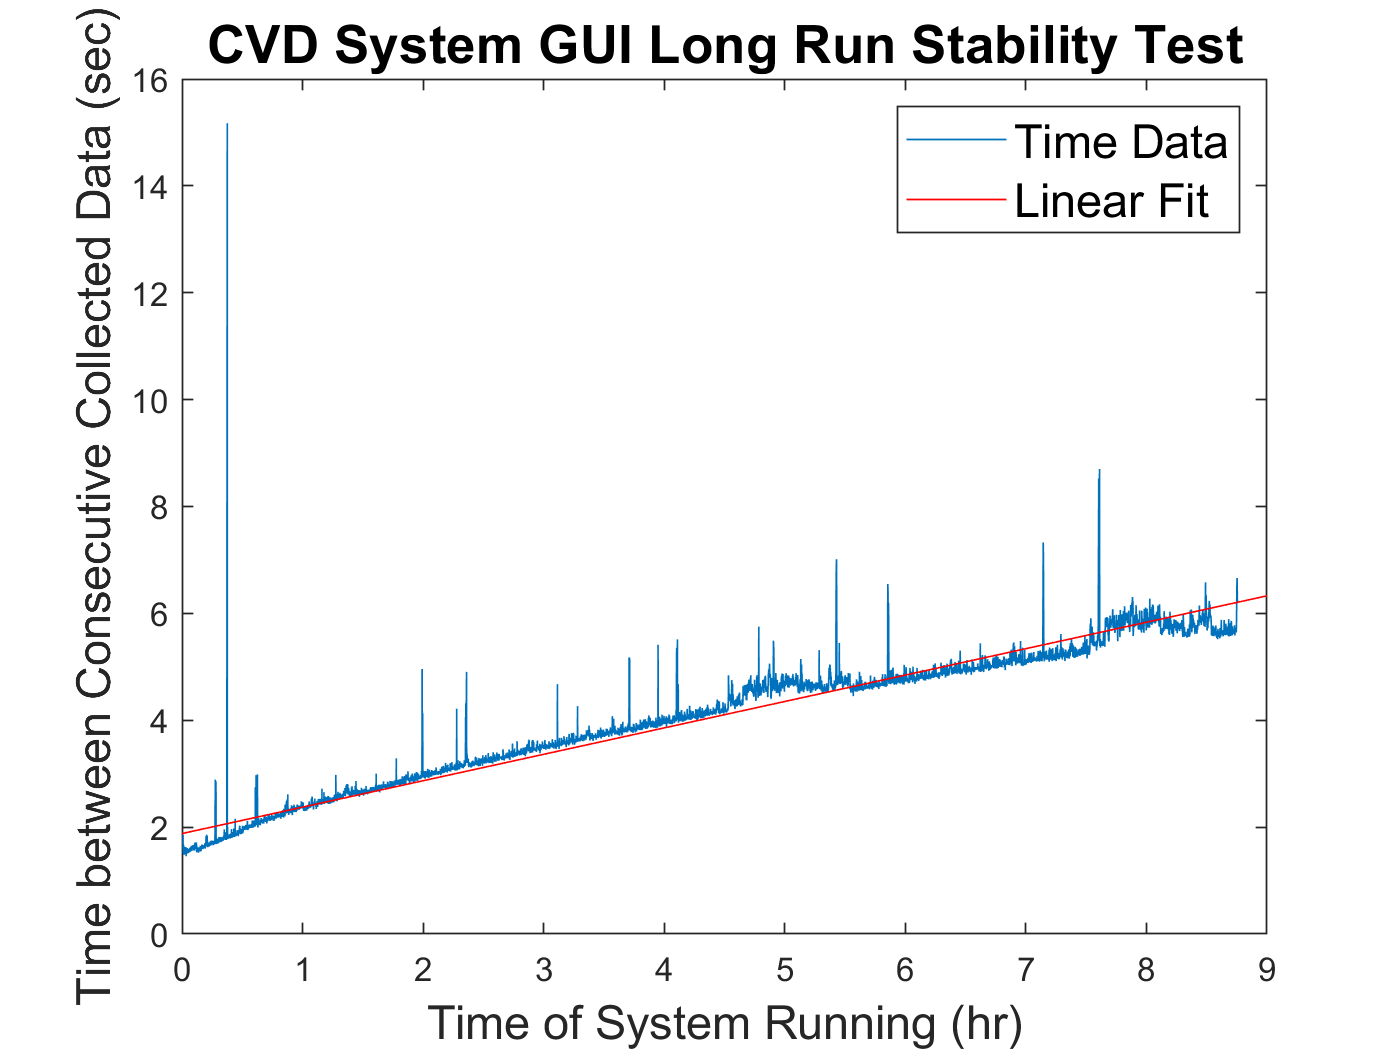

plot(times(2:end)/3600,intervals)
hold on
plot(fit(times(2:end)/3600,intervals','poly1'))
hold off
title('CVD System GUI Long Run Stability Test','fontsize', 16)
xlabel('Time of System Running (hr)','fontsize', 14)
ylabel('Time between Consecutive Collected Data (sec)','fontsize', 14)
legend('Time Data','Linear Fit','fontsize', 14)
xlim([0,9])